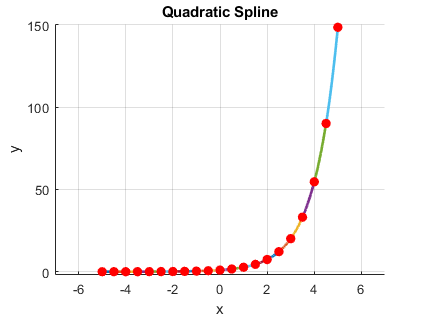

% s1, s2, s3, s4 - evaluarile Spline
% [a, b, c, d] - coeficientii Spline
x   =   -5:0.5:5;
y   =   exp(x);
N   =   length(x)-1;
% The unknowns are 3*N with ao=0 "Linear Spline"
% Filling Matrix from point matching
V   =   [0;zeros(2*N,1);zeros(N-1,1)];
Z   =   zeros(length(V),length(V));
j=1;
f=1;
for i=2:2:2*N    
    Z(i,f:f+2)          =   [x(j)^2 x(j) 1];
    V(i)                =   y(j);
    j                   =   j+1;
    Z(i+1,f:f+2)        =   [x(j)^2 x(j) 1];  
    V(i+1)              =   y(j);
    f                   =   f+3;
end
% Filling Matrix from smoothing condition
j=1;
l=2;
for i=2*N+2:3*N
    
    Z(i,j:j+1)            =   [2*x(l) 1];
    Z(i,j+3:j+4)          =   [-2*x(l) -1];
    j                     =   j+3;
    l                     =   l+1;
end
% Adjusting the value of a1 to be zero "Linear Spline"
Z(1,1)=1;
% Inverting and obtaining the coeffiecients, Plotting
Coeff       =       Z\V;

% N = length(x_data) - 1; % Get the number of data points (minus 1)
a = zeros(1, N);
b = zeros(1, N);
c = zeros(1, N);

for i = 1:N
    a(i) = Coeff(3 * i - 2);
    b(i) = Coeff(3 * i - 1);
    c(i) = Coeff(3 * i);
end

% y_val = a(i) * x_val^2 + b(i) * x_val + c(i);    
j=1;
hold on;
for i=1:N
    curve=@(l) Coeff(j)*l.^2+Coeff(j+1)*l+Coeff(j+2);
    ezplot(curve,[x(i),x(i+1)]);
    hndl=get(gca,'Children');
    set(hndl,'LineWidth',2);
    hold on
    j=j+3;
end
scatter(x,y,50,'r','filled')
grid on;
xlim([min(x)-2 max(x)+2]);
ylim([min(y)-2 max(y)+2]);
xlabel('x');
ylabel('y');
title('Quadratic Spline')



d=[-1, 3]; % derivata e^x
t=linspace(-1,1,200)';
x=-1:1; y=x.^3;

% complete
[a1,b1,c1,d1]=CubicSpline(x,y,d,0)

a1 =     -2
     2


b1 =      3
    -1


c1 =     -1
     1


d1 =     -1
     0


s1=evaluate_spline(x,a1,b1,c1,d1,t)

s1 =    -1.0000
   -1.0097
   -1.0189
   -1.0275
   -1.0355
   -1.0429
   -1.0498
   -1.0562
   -1.0620
   -1.0674



% derivate secunde
[a2,b2,c2,d2]=CubicSpline(x,y,d,1);
s2=evaluate_spline(x,a2,b2,c2,d2,t)

s2 =    -1.0000
   -0.9859
   -0.9723
   -0.9590
   -0.9460
   -0.9334
   -0.9212
   -0.9094
   -0.8979
   -0.8868



% naturale
[a3,b3,c3,d3]=CubicSpline(x,y,[0, 0],2);
s3=evaluate_spline(x,a3,b3,c3,d3,t)

s3 =    -1.0000
   -0.9901
   -0.9803
   -0.9708
   -0.9614
   -0.9523
   -0.9433
   -0.9346
   -0.9261
   -0.9177



% deBoor
[a4,b4,c4,d4]=CubicSpline(x,y,[0, 0], 3);

s4=evaluate_spline(x,a4,b4,c4,d4,t)

s4 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


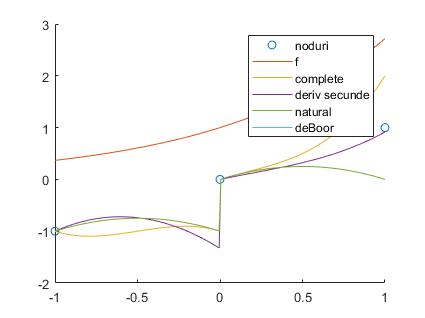


figure;
hold on;


% problema 3 - curbe spline parametrice
yg=exp(t);
plot(x,y,'o',t,[yg,s1,s2,s3,s4])
legend('noduri','f','complete', 'deriv secunde', 'natural', 'deBoor')

hold off;


%problema 2
x = 1 : 10;
t = 0.5 : 1 : 9.5;
y = sin(x);
yy = cos(x);
figure;
hold on;
fplot(@sin, [1, 10], 'r');

[a, b, c, d] = CubicSpline(x, y, yy,0);
result = evaluate_spline(x, a, b, c, d, t);
fprintf("%f", result);

0.3193490.8572040.734543-0.063013-0.802820-0.804219-0.0672320.7353050.8478650.232932

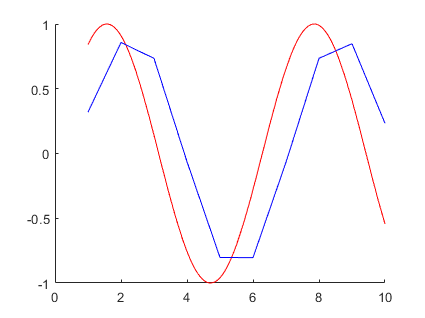

plot(result, 'b');